## **Driver test program to check Clothoids library**

**Test Intersection**

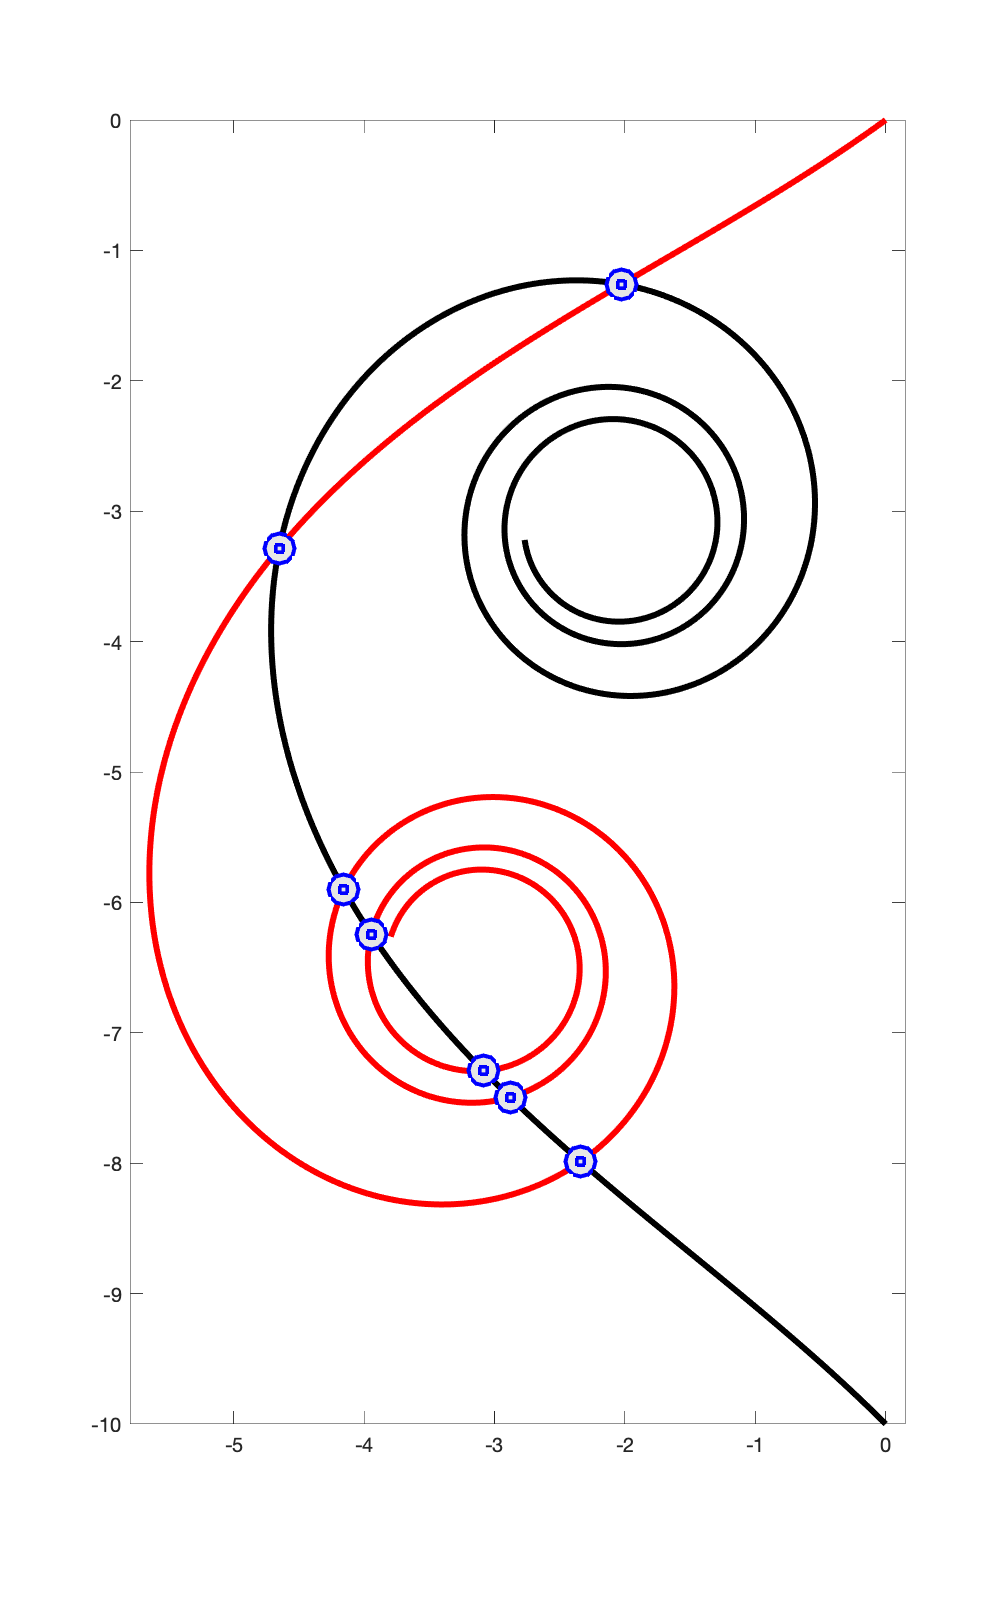

close all;
figure('Position',[1,1,500,800]);

x0     = 0;
y0     = 0;
theta0 = pi*0.7;
k0     = -0.1;
dk     = 0.05;
L      = 30;
C1 = ClothoidCurve( x0, y0, theta0, k0, dk, L );

x0     = -10;
y0     = 0;
theta0 = pi/4;
k0     = 0.1;
dk     = -0.05;
L      = 30;
C2 = ClothoidCurve( x0, y0, theta0, k0, dk, L );

npts = 1000;

C1.rotate(pi/2,0,0);
C2.rotate(pi/2,0,0);

C1.plot(npts,'Color','red','LineWidth',3);
hold on;
C2.plot(npts,'Color','black','LineWidth',3);

[s1,s2] = C1.intersect( C2 );

XY1 = C1.eval( s1 );
XY2 = C2.eval( s2 );

plot( XY1(1,:), XY1(2,:), 'o', ...
      'LineWidth',2,...
      'MarkerSize',15,...
      'MarkerEdgeColor','blue',...
      'MarkerFaceColor',[0.9,0.9,0.9] );
plot( XY2(1,:), XY2(2,:), 's', ...
      'LineWidth',2,...
      'MarkerSize',5,...
      'MarkerEdgeColor','b',...
      'MarkerFaceColor',[0.9,0.9,0.9] );

axis equal;